Te = 1;

num1 = [10];
den1 = [1 10 0];
[numd1, dend1] = c2dm(num1, den1, Te, 'zoh');
G1 = tf(numd1, dend1, Te)


G1 =
 
   0.9 z + 0.09995
  ------------------
  z^2 - z + 4.54e-05
 
Sample time: 1 seconds
Discrete-time transfer function.



num2 = [1];
den2 = [1 2];
[numd2, dend2] = c2dm([num2 0], den2, Te, 'zoh');
G2 = tf([numd2 0], conv(dend2, [1 -1]), Te)


G2 =
 
         z^2 - z
  ----------------------
  z^2 - 1.135 z + 0.1353
 
Sample time: 1 seconds
Discrete-time transfer function.



G0 = series(G1, G2)


G0 =
 
           0.9 z^3 - 0.8001 z^2 - 0.09995 z
  --------------------------------------------------
  z^4 - 2.135 z^3 + 1.271 z^2 - 0.1354 z + 6.144e-06
 
Sample time: 1 seconds
Discrete-time transfer function.


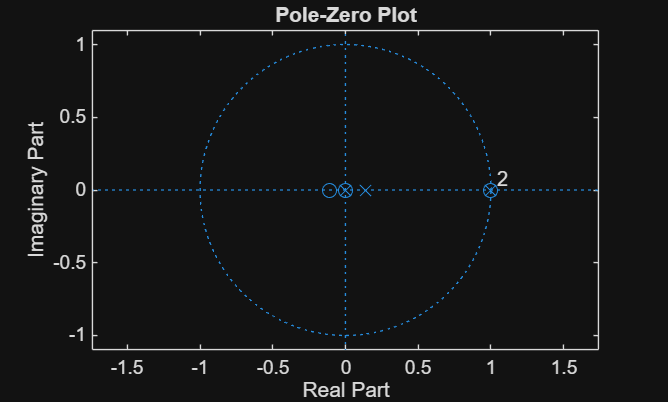


zplane(G0.Numerator{1},G0.Denominator{1})